table = readtable("LA_Baseline_Alt_processed_smoothed.txt");
table.Var2 = table.Var2 .* 100;
table.alt = atmospalt(table.Var2)

table = 3000×4 table
    Var1     Var2      Var3      alt  
    _____    _____    ______    ______

    0.005    82793    22.465    1671.4
    0.015    82792    22.467    1671.5
    0.025    82793    22.469    1671.4
    0.035    82794    22.472    1671.3
    0.045    82794    22.474    1671.3
    0.055    82794    22.477    1671.2
    0.065    82794     22.48    1671.2
    0.075    82794    22.481    1671.2
    0.085    82794    22.484    1671.3
    0.095    82794    22.486    1671.3
    0.105    82793    22.487    1671.4
    0.115    82793    22.489    1671.4
    0.125    82793     22.49    1671.4
    0.135    82793    22.491    1671.4
    0.145    82793    22.493    1671.4
    0.155    82794    22.494    1671.3


table.altf = convlength(table.alt,'m','ft')

table = 3000×5 table
    Var1     Var2      Var3      alt       altf 
    _____    _____    ______    ______    ______

    0.005    82793    22.465    1671.4    5483.5
    0.015    82792    22.467    1671.5    5483.9
    0.025    82793    22.469    1671.4    5483.5
    0.035    82794    22.472    1671.3    5483.2
    0.045    82794    22.474    1671.3    5483.2
    0.055    82794    22.477    1671.2      5483
    0.065    82794     22.48    1671.2      5483
    0.075    82794    22.481    1671.2    5483.1
    0.085    82794    22.484    1671.3    5483.3
    0.095    82794    22.486    1671.3    5483.3
    0.105    82793    22.487    1671.4    5483.5
    0.115    82793    22.489    1671.4    5483.5
    0.125    82793     22.49    1671.4    5483.5
    0.135    82793    22.491    1671.4    5483.5
    0.145    82793    22

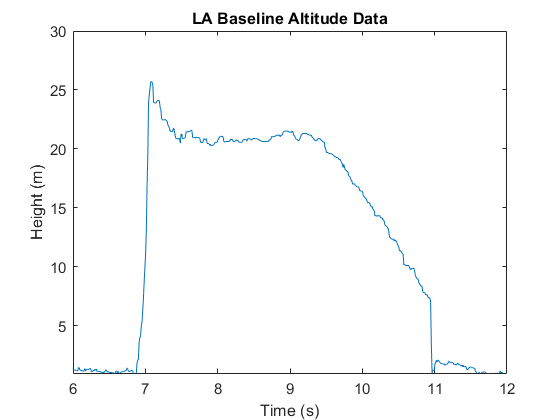

plot(table.Var1,table.alt)
set(gca,'FontSize',11)
title("LA Baseline Altitude Data")
xlim([6 12])
ylim([1671 1700])
yticklabels(["5","10","15","20","25","30"])
xlabel("Time (s)")
ylabel("Height (m)")